
clear all;
close all;


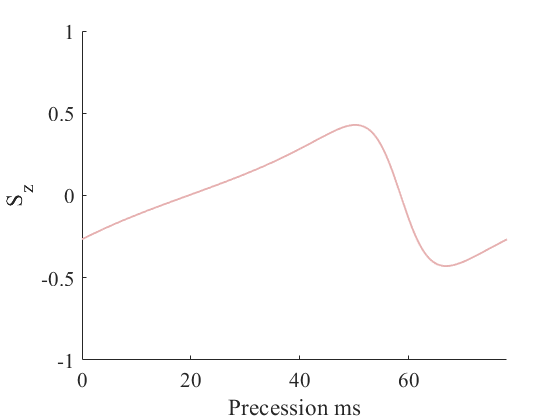


colors = npg(100);
F=5/2;
sigmax = spinOp(F,'x');
sigmay = spinOp(F,'y');
sigmaz = spinOp(F,'z');

initial = zeros(2*F+1,1);
initial(1) = 1;

timelist = [0:0.1:78];

%% 输入变量
tensor = 0.01;
Bz = 2*pi*1/78/5;   % omega量纲, 2pi*kHz, 对应ms

pop_state1 = 0;
pop_state2 = 0;

ROT = sigmax+sigmax^2;
ham = Bz*sigmaz+tensor*sigmaz^2;   % omega量纲
for k = 1:length(timelist)
    temp = ham_evolve(ROT,initial,pi/2);
    temp = ham_evolve(ham,temp,timelist(k));
    temp = ham_evolve(ROT,temp,pi/2/8);
    temp = ham_evolve(ham,temp,78*5);
    temp = ham_evolve(ROT,temp,pi/8);
    temp = ham_evolve(ham,temp,78*5);
    %precess_state1(:,k) = ham_evolve(ROT,temp,pi/2);
    precess_state1(:,k) = ham_evolve(ROT,temp,pi/2-pi*(1/8+1/16));
    precess_state2(:,k) = ham_evolve(ROT,precess_state1(:,k),pi);
end
pop_state1 = abs(precess_state1).^2;
pop_state2 = abs(precess_state2).^2;


state1 = pop_state1;
state2 = pop_state2;

sz(:) = (state1(1,:)-state2(1,:))./(state1(1,:)+state2(1,:));


f1 = figure; hold on;

plot(timelist,sz,'-','LineWidth',1.4,'Color',[0.9 0.69 0.69]);
ylim([-1 1]);
xlim([min(timelist) max(timelist)]);
xlabel('Precession ms');
ylabel('S_z');

set(gca,'FontName','times new roman','FontSize',16);


set(f1,'Visible','on');

function final = ham_evolve(ham,initial,time)
try
    final = expm(-1i*ham.*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end

